# IEM_spatial.m

adapted from 

    Tommy Sprague, 3/11/2015 - Bernstein Center IEM workshop

    tommy.sprague@gmail.com or jserences@ucsd.edu

% Uses a dataset acquired by Sirawaj Itthipuripat and Tommy Sprague, results
% from which were presented at VSS 2014 and will be presented at VSS 2015 
%
%
% Please DO NOT use data from these tutorials without permission. Feel free
% to adapt or use code for teaching, research, etc. If possible, please
% acknowledge relevant publications introducing different components of these
% methods (Brouwer & Heeger, 2009; 2011; Serences & Saproo, 2012; Sprague & Serences, 2013; 
% Sprague, Saproo & Serences, 2015).  And please feel free to contact us
% with any questions, comments, or concerns. Also see serenceslab.ucsd.edu
% for any publications from our lab. 
%
% This file guides the user through analyses of a dataset acquired with the
% goal of spatial reconstruction of visual stimuli using an inverted
% encoding model (IEM) (see Sprague, Saproo & Serences, 2015, TICS).
% Participants viewed peripheral flickering checkerboard stimuli presented
% at a range of contrasts (0-70%, logarithmically spaced) while performing
% either a demanding target detection task (contrast change) at the
% stimulus position ("attend stimulus" condition) or at the fixation point
% ("attend fixation" condition). The stimuli appeared randomly on the left
% or right side of the screen. Targets appeared rarely, and trials in which
% targets do appear are not included in analyses. Thus, sensory
% conditions are perfectly equated across the attend stimulus and the
% attend fixation conditions.
%
% In addition to this main attention task, paricipants also performed a
% "spatial mapping" task in which they viewed small checkerboard discs
% presented at different positions on the screen while they performed a
% demanding fixation task (contrast change detection). 



## Setup


close all; clear;

setup

## load the data

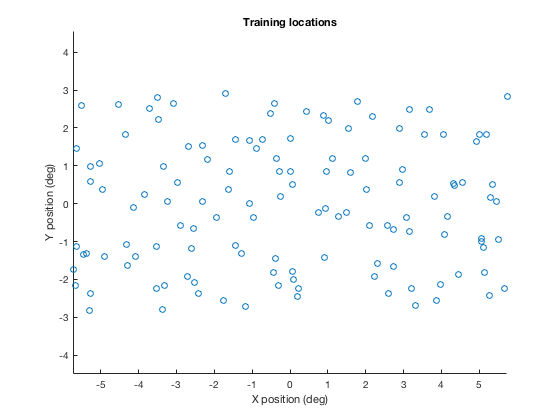

load('fMRI_spatial/AL61_Bilat-V1_attnContrast.mat');


% you'll find several variables:
% - tst: the task data - each row is a trial, each column a voxel
% - trn: the encoding model estimation data - each row is a trial, each
%   column is a voxel. the number of columns should be the same in trn & tst
% - trn_r: run number for encoding model estimation data
% - tst_r: run number for task data
% - trn_conds: condition labels for each trial of the encoding model
%   estimation data, where columns indicate:
%    - 1: x position of center of training stimulus in DVA
%    - 2: y position of center of training stimulus in DVA (SCREEN COORDS!)
% - tst_conds: condition labels for each trial of the task data, where columns indicate:
%    - 1: whether the stimulus appeared on the left or right of the screen
%         (1 or 2)
%    - 2: contrast level (1-6, 1 being the lowest, 6 being the highest)
%    - 3: task condition (attend fixation, 1, or attend stimulus, 2)
%    - 4: target present? (0: no, 1: yes)


figure, scatter(trn_conds(:,1), trn_conds(:,2)); axis equal;
title('Training locations');
xlabel('X position (deg)')
ylabel('Y position (deg)')

## train encoding model

this is broken up into several subtasks - the first of which is generating a stimulus mask. Because the stimulus is a circle w/ a known, jittered location on each trial, we can just generate a binary image of 0's and 1's, with 1's at the positions subtended by the stimulus and 0's elsewhere. A similar technique is used by those mapping population receptive fields (pRFs).(Dumoulin & Wandell, 2008; Kay et al, 2013)

This trial-by-trial stimulus mask will then be projected onto each channel's filter (a 2-d Gaussian-like function, usually). This amounts to a reduction in dimensionality from n_pixels to n_channels, though the transformation is necessarily lossy in this framework

Use the trn_conds coordinates (first column is x, second column is y), and the stimulus size of 1.449 dva to generate a stimulus mask of 1's and 0's. The visual field area subtended by the display was 16.128 dva horizontally and 9.072 dva vertically (full width/height edge-to-edge).

At this stage, it doesn't matter if we overestimate the size of the screen, so for simplicity let's say the screen is 10 dva tall and 17 dva wide.

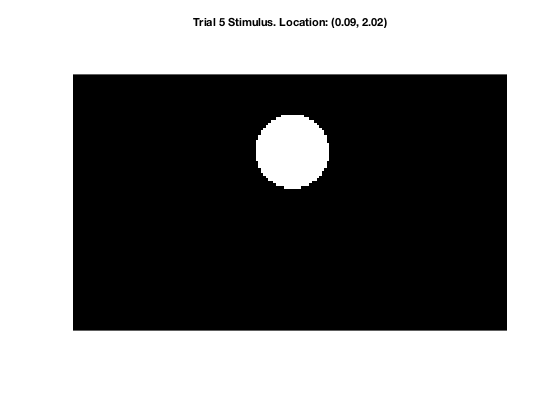

trn_conds(:,2) = trn_conds(:,2)*-1; % flip to cartesian coordinates to make life easier
stim_size = 1.449; % stimulus radius

% we also need to decide on a resolution at which to compute stimulus masks
% and spatial filters (below) - let's do 171 (horiz) x 101 (vert)

res = [171 101];

[xx, yy] = meshgrid(linspace(-17/2,17/2,res(1)),linspace(-10/2,10/2,res(2)));
xx = reshape(xx,numel(xx),1);yy = reshape(yy,numel(yy),1);

stim_mask = zeros(length(xx),size(trn_conds,1));

for ii = 1:size(trn_conds,1)
    
    rr = sqrt((xx-trn_conds(ii,1)).^2+(yy-trn_conds(ii,2)).^2);
    stim_mask(rr <= stim_size,ii) = 1; % assume constant stimulus size here
    
end



% check the stimulus masks by plotting a column of the stimulus mask as an
% image
tr_num = 5;
figure;
this_img = reshape(stim_mask(:,tr_num),res(2),res(1)); % x, y are transposed here because images are row (y), column (x)
imagesc(xx,yy,this_img);colormap gray; axis xy equal off;
title(sprintf('Trial %i Stimulus. Location: (%0.02f, %0.02f)',tr_num,trn_conds(tr_num,1),trn_conds(tr_num,2)));

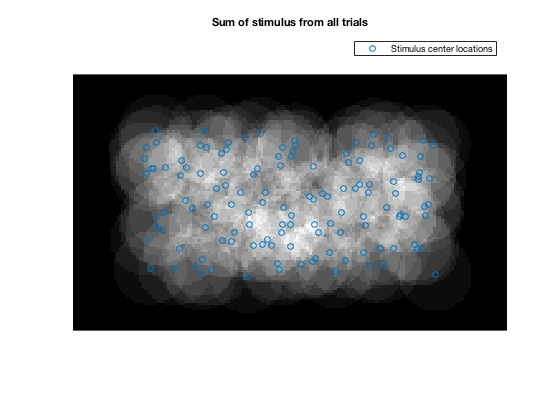

% Spot-check a few trials - does everything look ok? Also try plotting a
% figure showing  In this particular
% experiment, we randomized the position of each and every trial (relative
% to a fixed grid). This means that there will not necessarily be perfectly
% even coverage of the entire screen, but it does increase the number of
% unique stimulus positions we can use for encoding model estimation.


% view all the trials superimposed (summed)
stim_mask3D = sum(reshape(stim_mask, res(2), res(1), []),3);
figure,
imagesc(xx, yy, stim_mask3D); colormap gray; axis xy equal off;
% superimpose the stimulus centers
hold on; scatter(trn_conds(:,1), trn_conds(:,2));
title('Sum of stimulus from all trials');
legend('Stimulus center locations')

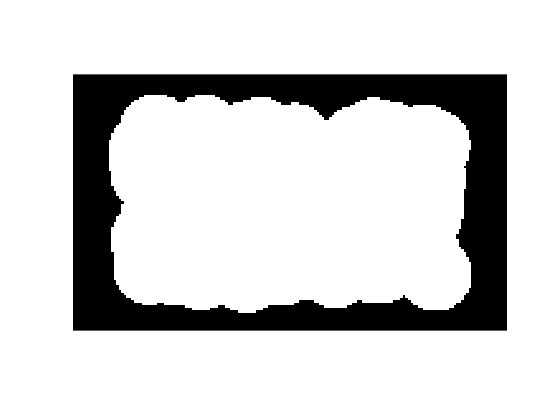


% The visual field coverage - the extent of the screen
% subtended by *any* stimulus, across all trials.
figure,
imagesc(xx, yy, stim_mask3D>0); colormap gray; axis xy equal off;

## Build an encoding model

an encoding model describes how a neural unit responds to an arbitrary set of stimluli. A common encoding model for visual stimuli measured for decades in the spatial receptive field (RF). Rather than directly estimate the exact receptive field of each voxel, we'll instead suppose that there are a discrete number of possible RF positions (that is, a discrete number of spatial filters) which describe discrete neural subpopulations. Each voxel then can be modeled as a weighted sum of these discrete subpopulations. While this is of course an approximation of the actual nature of RF properties in the visual system, by supposing a small number of possible RF positions/subpopulations we can **invert** the estimated encoding model (which is a set of weights on each supopulation for each voxel) in order to reconstruct the activation of each population given a novel voxel activation pattern observed (below). 

First, let's generate the filters corresponding to our hypothetical neural populations. We'll assume, for simplicity, that they are a square grid and are all the same "size" (FWHM). If interested, try varying these parameters. 

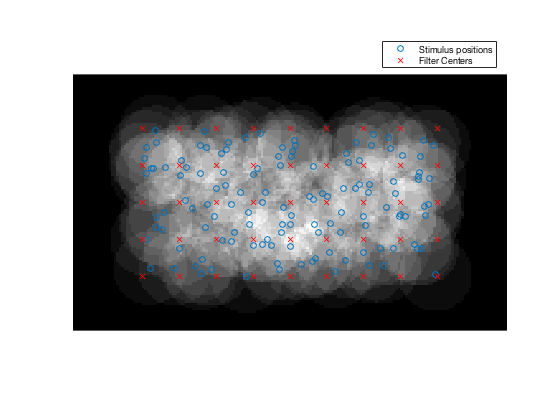

% Let's set the center points:
rfPtsX = [-4:4] * stim_size;
rfPtsY = [-2:2] * stim_size;
[rfGridX,rfGridY] = meshgrid(rfPtsX,rfPtsY); 
rfGridX = reshape(rfGridX,numel(rfGridX),1);rfGridY = reshape(rfGridY,numel(rfGridY),1);
rfSize = 1.25*stim_size;   % for the filter shape we use (see below), this size/spacing ratio works well (see Sprague & Serences, 2013)


figure,
imagesc(xx, yy, stim_mask3D); colormap gray; axis xy equal off; hold on; 
% superimpose the stimulus centers
scatter(trn_conds(:,1), trn_conds(:,2));
scatter(rfGridX, rfGridY, 'rx')
legend('Stimulus positions', 'Filter Centers')


% because we're projecting a stimulus mask onto a lower-dimensional set of
% filters, we call the set of filters (or information channels) our basis
% set

basis_set = nan(size(xx,1),size(rfGridX,1)); % initialize

for bb = 1:size(basis_set,2)
    
    % the form of the basis function I use is a gaussian-like blob which
    % reaches zero at a known distance from its center, which is 2.5166x
    % the FWHM of the function. We'll define the FWHM as rfSize (above),
    % which means the "size" parameter of our function is 2.5166*rfSize.
    %
    % I've made a function (make2dcos) which we can use for generating each
    % individual basis function
    
    % basis_set(:,bb) = make2dcos(xx,yy,rfGridX(bb),rfGridY(bb),rfSize*2.5166,7);
    basis_set(:,bb) = make2dcos(xx,yy,rfGridX(bb),rfGridY(bb),rfSize*2.5166,7);
end


## Basis set

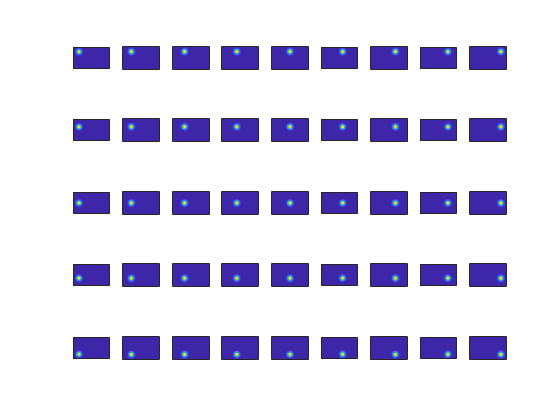

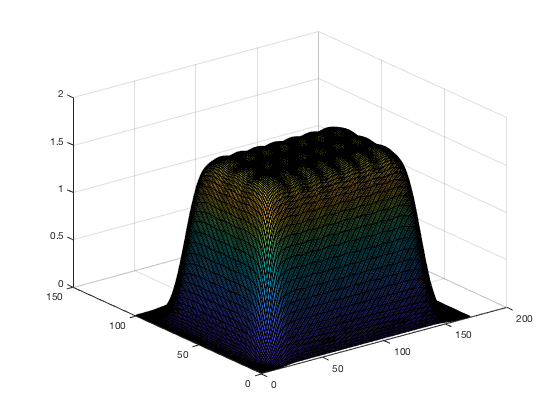

% I've created a function "plot_basis_rect" which takes a matrix of the
% basis set, number of X & Y points spanned by the basis set, and the x/y
% resolution of each filter. The function plots all basis functions
% (filters), as well as a surface plot showing the sum of all filters

plot_basis_rect(basis_set',length(rfPtsX),length(rfPtsY),res(1),res(2));


% You can see that we've created a set of spatial RFs which span the space
% subtended by our mapping stimulus. Additionally, the second figure shows
% the "coverage" of the basis set, as well as the "smoothness" of its
% coverage over space. In our experience, this
% approxmimate ratio of FWHM:spacing for a square grid works well. A
% hexagonal grid of basis functions also works well, and in that case
% because the mean distance between each basis function is slightly
% smaller, the best FWHM:spacing ratio is also slightly smaller.
% 
% Above, you can try changing the size of each basis function by changing
% the "1" before "rfSize" in the call to make2dcos - try bigger and smaller
% basis function sizes. What are the advantages and disadvantages to each?
% Come back to this once you've reached the end of the tutorial and try
% processing the data w/ several basis function sizes.

## Compute predicted channel responses

Now that we have a stimulus mask and a set of spatial filters/information channels, we want to determine the contribution of each information channel (hypothetical neural population) to each voxel. We set up the problem like a standard general linear model often used for fMRI activation map-based analyses: y = beta*X, where: - y is the measured signal in a voxel across all trials (1 x n_trials) - beta is the weights corresponding to how much each channel's response contributes to each voxel (stable across trials, 1 x n_channels) - X is a design matrix, which is how much each hypothetical population, with its defined RF, should respond to the stimulus (which we know) (n_trials x n_channels)

note that X is the same design matrix used for any standard GLM-based analysis in fMRI - we're just defining our "predictors" a bit differently. Here, predictors are predicted channel responses to known stimuli on each trial (the stimulus mask above). 

In order to compute the design matrix, we simply compute the overlap of the stimulus mask onto each channel. 

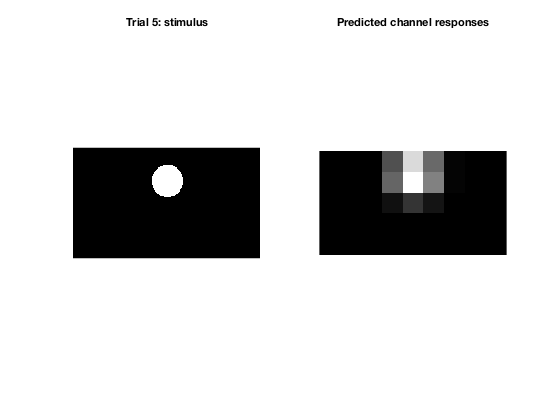

trnX = stim_mask.' * basis_set;
trnX = trnX./max(trnX(:));        % and normalize to 1


% now let's double-check our filtering by plotting the predicted channel
% responses for a given trial next to the stimulus mask for that trial
tr_num = 5;
figure;
subplot(1,2,1);
imagesc(xx,yy,reshape(stim_mask(:,tr_num), res(2),res(1)));
axis xy equal off;
title(sprintf('Trial %i: stimulus',tr_num));

subplot(1,2,2);
imagesc(rfPtsX,rfPtsY,reshape(trnX(tr_num,:),length(rfPtsY),length(rfPtsX)));
axis xy equal off;
title(sprintf('Predicted channel responses'));
colormap gray;

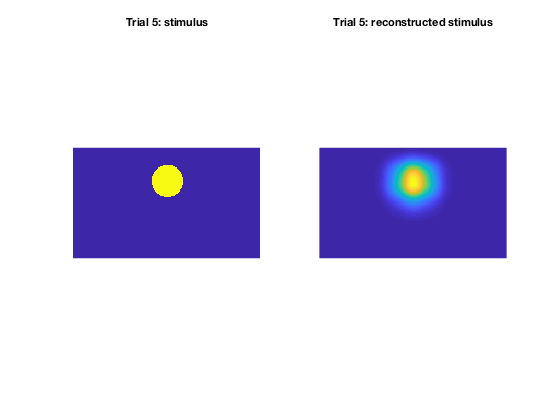


% Look at a reconstructed stimulus
reconstructedStimuli = basis_set * trnX';

figure;
subplot(1,2,1);
imagesc(xx,yy,reshape(stim_mask(:,tr_num), res(2),res(1)));
axis xy equal off;
title(sprintf('Trial %i: stimulus',tr_num));

subplot(1,2,2);
imagesc(xx,yy,reshape(reconstructedStimuli(:,tr_num), res(2),res(1)));
axis xy equal off;
title(sprintf('Trial %i: reconstructed stimulus',tr_num));

% Note that the model is NOT fully invertible
%  It can't be since there are more pixels than channels - the space of 2D
%    positions (ie a gray-scale image) is large: the number of possible
%    binary images 171 x 101 is 2^(171*101), essentially infinite
%  
% This differs from inverted encoding models of lower dimensional spaces
%    such as hue (Brouwer and Heeger, 2009). Hue is a circular space, and
%    can be exactly recovered from the (noiseless) outputs of a few
%    filters.

## Estimate channel weights using training data

Now that we have our design matrix and our measured signal, we need to solve for the weights ("betas" in above equation). Because we have more trials than channels, and because our stimulus positions are unique on each trial, we should be able to estimate a unique solution for the channel weights given our observed activation pattern using ordinary least squares regression. 

% first, let's be sure our design matrix is "full-rank" (that is, that no
% predicted channel responses are colinear). This is always important to
% check, and could come about if you're using channels that are not
% uniquely sampled by the stimulus set. For example, if above you multiply
% the rfPtsX, rfPtsY vectors each by 3 before generating the design matrix,
% you would notice that many of the channels (those correspondign to the
% edges of the display) will always have "0" predicted activity. This means
% that it is impossible to estimate the contribution of such a channel to
% the activation of a voxel. This is also why we can only model the
% stimulated portion of the screen along model dimensions which we control.
% As an example, V1 also has many orientation-selective populations (see
% IEM_ori_fMRI.m), but we did not systematically vary the stimulus orientation
% here, and so we cannot uniquely estimate the contribution of different
% oreintation-selective populations to the observed voxel activations in
% this dataset.
%
% As a thought exercise, what are other scenarios (stimulus conditions or
% hypothesized channel properties like size/position) which could result in
% design matrices w/out full rank?

fprintf('Rank of design matrix: %i\n',rank(trnX));

Rank of design matrix: 45



% So we've established that the design matrix is full-rank (the rank is
% equal to the number of columns). Let's estimate the channel weights.

% this is just pinv(trnX) * trn; - but I wrote out the full math for
% completness
w = inv(trnX.'*trnX)*trnX.' * trn; 

% (the above can also be written as: w = trnX\trn; )

% w is now n_channels x n_voxels. This step is massively univariate, and is
% identical to the step of estimating the beta weight corresponding to each
% predictor for each voxel in a standard fMRI GLM analysis. It's written
% above as a single matrix operation for brevity, but identical results are
% obtained when looping through individual voxels. 
%

% what would happen if there were fewer trials than channels?
trials = 1:30;
trnXX = trnX(trials, :);
ww = inv(trnXX.'*trnXX)*trnXX.' * trn(1:30,:); 


% or many trials but with few conditions?
% what would happen if there were fewer trials than channels?
trials = ones(1, size(trn,1));
trnXX = trnX(trials, :);
ww = inv(trnXX.'*trnXX)*trnXX.' * trn(trials,:);

## Invert the encoding model and compute channel responses

Our estimated "w" above reflects an ENCODING MODEL for each voxel. For a given region (here, V1), we have an encoding model estimated for each voxel. Given our linear framework described above, we can INVERT the encoding model in order to estimate the channel activation pattern (like our trnX) which is associated with any novel activation pattern that is observed. The associated mapping from VOXEL SPACE into CHANNEL SPACE is computed from the pseudoinverse of the estimated weight matrix.

This inversion step is where we get "inverted" encoding model from - we're not just estimating encoding models for single voxels and comparing them; we're instead estimating all encoding models, and using the joint set of encoding models to constrain a mapping from voxel space into channel space. 

Once we have the inverted mapping (the pseudoinverse), we can map the novel activation pattern ("tst") back into channel space.

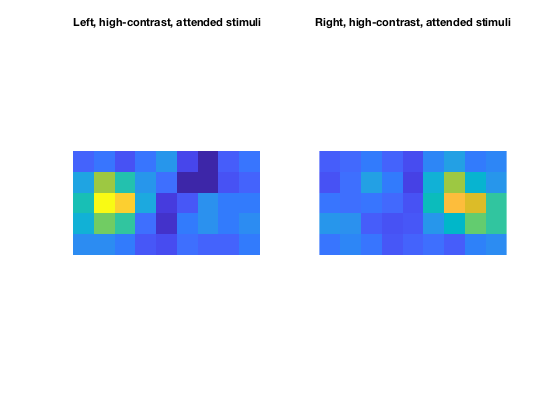

chan_resp = (inv(w*w')*w*tst').';  
% or can write as chan_resp = (w.'\tst.').'

% "chan_resp" is now the estimated channel responses for a novel dataset
% which was never used to estimate any encoding properties (that is, "tst"
% was never used in the computation of "w"). Each column of chan_resp
% corresponds to a channel, or hypothetical neural population response, and
% each row corresponds to a trial.


% Let's see what the channel responses look like across different trial
% types. For now, let's just look at high-contrast stimuli presented on the
% right side of the screen on attend-stimulus trials. 
%
% This means we'll search for trials with the following values in each of
% tst_conds' columns:
% column 1 (stimulus side, L or R):  1
% column 2 (stimulus contrast, 1-6): 6
% column 3 (task condition, attend fix or attend stim): 2
% column 4 (target present?): 0 (so that mean contrast is the same)
% 

thisidx = tst_conds(:,1)==1 & tst_conds(:,2)==6 & tst_conds(:,3)==2 & tst_conds(:,4)==0;
avg_chan_resp = mean(chan_resp(thisidx,:),1);
figure;ax(1)=subplot(1,2,1);
imagesc(rfPtsX,rfPtsY,reshape(avg_chan_resp,length(rfPtsY),length(rfPtsX)));
title('Left, high-contrast, attended stimuli');
axis equal xy off;

% now compare to trials when the stimulus was on the right

clear thisidx avg_chan_resp;
thisidx = tst_conds(:,1)==2 & tst_conds(:,2)==6 & tst_conds(:,3)==2 & tst_conds(:,4)==0;
avg_chan_resp = mean(chan_resp(thisidx,:),1);
ax(2)=subplot(1,2,2);
imagesc(rfPtsX,rfPtsY,reshape(avg_chan_resp,length(rfPtsY),length(rfPtsX)));
title('Right, high-contrast, attended stimuli');
axis equal xy off;

% importantly, we want to be sure all the axes are on the same color-scale.
% I wrote a function you can use for that called "match_clim", which takes
% a set of axis handles as inputs, and optionally a new set of clim values
% as a second argument. 

match_clim(ax);

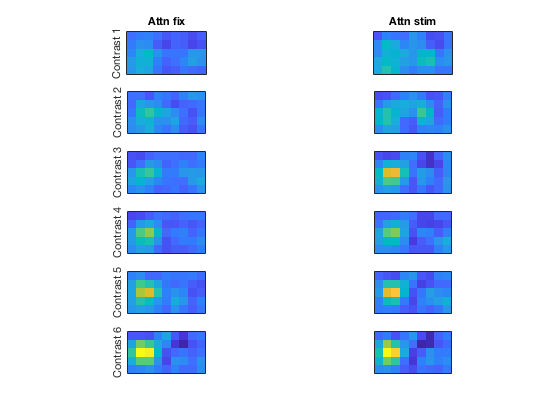

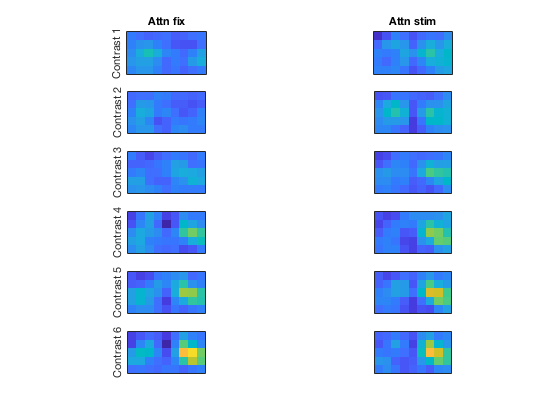


% It should be clear that the channels with RFs near the attended stimulus
% position are those which are most active when that sitmulus is present &
% attended.


% Let's check out all the conditions - the easiest way to do this is have
% one figure for stimuli on the left, and another figure for stimuli on the
% right.
ax = [];
task_str = {'Attn fix','Attn stim'};

for stim_side = 1:2
    figs(stim_side) = figure;
    for attn_cond = 1:2
        for stim_contrast = 1:6
            ax(end+1) = subplot(6,2,attn_cond+(stim_contrast-1)*2);
            thisidx = tst_conds(:,1)==stim_side & tst_conds(:,2)==stim_contrast & tst_conds(:,3)==attn_cond & tst_conds(:,4)==0;
            avg_chan_resp = mean(chan_resp(thisidx,:),1);
            imagesc(rfPtsX,rfPtsY,reshape(avg_chan_resp,length(rfPtsY),length(rfPtsX)));
            axis equal xy tight;
            if stim_contrast == 1
                title(task_str{attn_cond});
            end
            if attn_cond==1
                ylabel(sprintf('Contrast %i',stim_contrast));
            end
            set(gca,'XTick',[],'YTick',[]); % turn off xtick/yticks
            clear thisidx avg_chan_resp;
        end
    end
end
match_clim(ax);

## Compute stimulus reconstructions from channel responses

The channel response plots above are the **full** dataset, though sometimes it is useful to compute a stimulus reconstruction that can be more easily quanitfied by, e.g., curvefitting methods. Furthermore, the discrete values above are challenging to "coregister" across different stimulus position conditions (at least when stimuli are not simply at the same position on different sides of the screen). Take for example a scenario like Sprague, Ester & Serences, 2014 - during a spatial WM task, a remembered stimulus appeared at a random position along a ring of a given eccentricity. Because we were not interested in whether or not representations for stimuli at different positions were different from one another, we sought to average representations for stimuli at different positions together. We did this by reconstructing an "image" of the contents of WM via a weighted sum of the spatial filters for each channel. Let's try that here.

We have our basis_set, used to compute predicted channel responses, and we have our estimated channel responses (chan_resp) - to compute the weighted sum as an image, we just need to multiply the two.

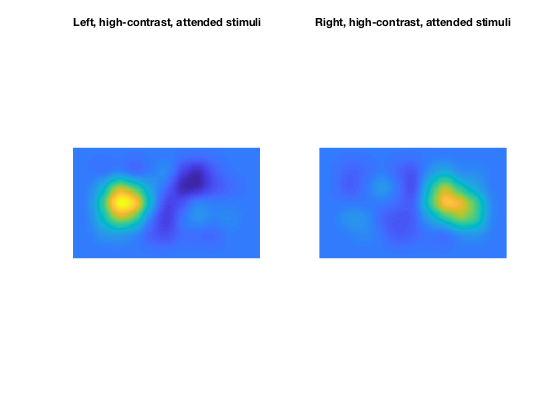

stim_reconstructions = chan_resp * basis_set.';

% Importantly, the dimensionality of each reconstruction remains equal to
% the number of channels used, but this enables easy averaging of stimuli
% at different positions (say, around a circular ring) by changing the
% basis set in order to "undo" the stimulus manipulation performed. See
% Sprague, Ester & Serences, 2014, for more details (Fig 2E). We won't go
% over that here. This discussion is mainly to illustrate that we gain no
% information in going from channel responses to stimulus reconstructions,
% but the added ability to coregister and average different stimuli affords
% better sensitivity to low-amplitude/low-SNR representations in stimulus
% reconstructions. 

% We can now do all the analyses we performed above on channel response
% amplitudes instead on stimulus reconstructions. For example:

clear ax;
% trials when stimulus was on the left
thisidx = tst_conds(:,1)==1 & tst_conds(:,2)==6 & tst_conds(:,3)==2 & tst_conds(:,4)==0;
avg_reconstruction = mean(stim_reconstructions(thisidx,:),1);
figure;ax(1)=subplot(1,2,1);
imagesc(xx,yy,reshape(avg_reconstruction,res(2),res(1)));
title('Left, high-contrast, attended stimuli');
axis equal xy off;

% now compare to trials when the stimulus was on the right

clear thisidx avg_chan_resp;
thisidx = tst_conds(:,1)==2 & tst_conds(:,2)==6 & tst_conds(:,3)==2 & tst_conds(:,4)==0;
avg_reconstruction = mean(stim_reconstructions(thisidx,:),1);
ax(2)=subplot(1,2,2);
imagesc(xx,yy,reshape(avg_reconstruction,res(2),res(1)));
title('Right, high-contrast, attended stimuli');
axis equal xy off;

match_clim(ax);

## combine non-like stimulus feature values

One of the biggest advantages of the IEM technique is that by transforming activation patterns into a "feature space" (here, spatial information channels), you have full knowledge of how your activation is related to feature values. Put another way, you know how to manipulate your feature space in order to coregister non-like trials. For example, here, we don't necessarily care too much about what may or may not be different in stimulus reconstructions computed from trials in which stimuli were on the left compared with trials when stimuli were on the right. Accordingly, we can average these trials after "coregistering" the reconstructions. Fortunately, this is an easy dataset to coregister. We just need to flip the reconstructions across the vertical meridan for one half of trials (sorted by trn_conds(:,1), which is the stimulus side). It doesn't matter whether we flip left trials onto the right side of the screen or vice versa. Try it below!

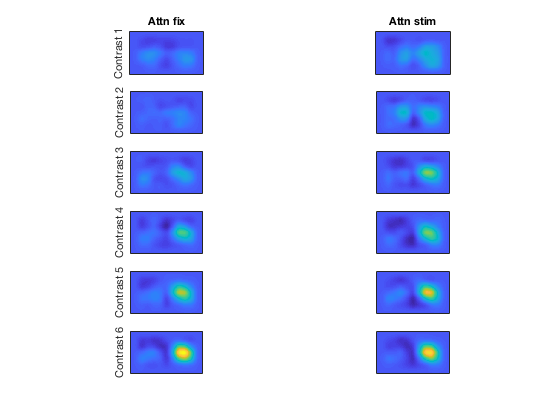

ans =    -0.1858    0.9109


% so that it's easy to "flip" the reconstructions, let's turn our
% reconstruciton matrix, in which each reconstruction occupies a row (n_trials x n_pixels), 
% into a reconstruction 3d-matrix in which each trial is the 3rd dimension,
% and each "slice" is a single-trial's stimulus reconstruction. It's
% easiest to make trial the 3rd dimension so that we don't need to
% "squeeze" the data later on.

stim_reconstructions_mat = reshape(stim_reconstructions',res(2),res(1),size(stim_reconstructions,1));

% now, look for all trials with tst_cond(:,1)==1 and "coregister" them by 
% flipping the slice of the matrix across the vertical axis (hint: FLIPLR)

stim_reconstructions_mat(:,:,tst_conds(:,1)==1) = fliplr(stim_reconstructions_mat(:,:,tst_conds(:,1)==1));



% now we can plot a similar figure as above, but with all trials on the
% same plot.

figure;ax = [];
for attn_cond = 1:2
    for stim_contrast = 1:6
        ax(end+1) = subplot(6,2,attn_cond+(stim_contrast-1)*2);
        thisidx = tst_conds(:,2)==stim_contrast & tst_conds(:,3)==attn_cond & tst_conds(:,4)==0;
        
        imagesc(xx,yy,mean(stim_reconstructions_mat(:,:,thisidx),3));
        axis equal xy tight;
        if stim_contrast == 1
            title(task_str{attn_cond});
        end
        if attn_cond==1
            ylabel(sprintf('Contrast %i',stim_contrast));
        end
        set(gca,'XTick',[],'YTick',[]); % turn off xtick/yticks
        clear thisidx avg_chan_resp;
    end
end
match_clim(ax)

## Plot a profile across the horizontal midline

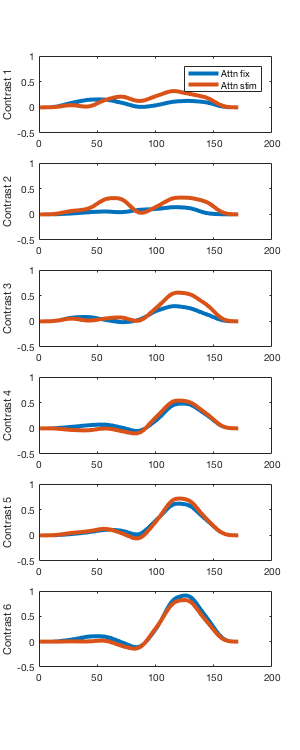

ans =      0     1



 figure;ax = []; set(gcf, 'Position', [100 100 300 750]);
for stim_contrast = 1:6
    ax(end+1) = subplot(6,1,stim_contrast);
    for attn_cond = 1:2
        
        thisidx = tst_conds(:,2)==stim_contrast & tst_conds(:,3)==attn_cond & tst_conds(:,4)==0;
        
        im = mean(stim_reconstructions_mat(:,:,thisidx),3);
        plot(im(51,:), 'LineWidth', 4); hold on;
    end
    %axis equal xy tight;
    if stim_contrast == 1
        legend(task_str);
    end
    ylabel(sprintf('Contrast %i',stim_contrast));
    ylim([-.5 1])    
end
match_clim(ax)